clc;
clear all;

# Data loading

load('.\Output Files\DoE Bosch (Dec 2018)_Matlab processed data_All runs.mat')
load('.\Input Files\DoE Process Parameter.mat')


Model_Bosch_DoE_Dec2018=struct(... %Initialize an empty structure to store modelized data
    'Run',{},...
    'Experimental_Data',{},...
    'Modelized_Data',{},...
    'Model_Dissolution_EndSpraying',{},...
    'Model_Dissolution_Discharge',{});

Choose to simulate one run or the all DoE

 Runs = [3]; 
 
 %Runs=linspace(1,20,20) %linspace (First run,Last Run, Number of Runs)
 
 Number_of_Runs=length(Runs);
 
for n=1:Number_of_Runs
 

We start by collecting data from experiments to compare them with the modelized data

    Run=Runs(n)
    

    
    Table_Run=(Bosch_DoE_Dec2018(Run).TabClean);
    
    ExpDissolution_EndSpraying=(Bosch_DoE_Dec2018(Run).Dissolution_EndSpraying);
    ExpDissolution_Discharge=(Bosch_DoE_Dec2018(Run).Dissolution_Discharge);
    
    Parameter=DoE_Process_Parameter(Run,:)



    i=1;
    j=1;
    l=1;
   

    for k=1:height(Table_Run)
    
        if Table_Run.ProcessPhase(k)== 'Preheat/dry   3'
        
        PreHeat(i,:)=Table_Run(k,:);
        i=i+1;
        end

        if Table_Run.ProcessPhase(k)== 'Spraying   4'
        
        Spraying(j,:)=Table_Run(k,:);
        j=j+1;
        end 
    
        if Table_Run.ProcessPhase(k)== 'Preheat/dry   5'
        
        Drying(l,:)=Table_Run(k,:);
        l=l+1;
        end 
        
    end
    
    

ExpData is a table containing experimental data of the run for Pre-Heating, Spraying and Drying phases.


ExpData=[PreHeat
    Spraying
    Drying];


# Characteristics

global  Flow_rate_coating absolute_humidity Temp_at Pressure ...
    Gas_moisture_0 Temp_air_heating  Flow_rate_air_heating  Temp_air_spraying Flow_rate_air_spraying ...
    Temp_air_drying Flow_rate_air_drying Process_parameter Flow_rate_at

global Gas_constant cp_p cp_dry_air cp_v DMC cp_c Temp_wb Molecular_weight_acetone Q_lat Volume_air rho_air Mass_air ...
    Molecular_weight_air Volume_bed

global N_bed Volume_particle Surface_particle Length_particle Mass_particle ... 
     rho_particle Diameter_eq Batch_size lambda_wall

## Equipment Characteristics

Enter all the physical parameter of the fluid bed

global Batch_size Diameter_bed Height_bed Volume_bed Wall_Thickness

Diameter_bed = 0.305; %(m)
Height_bed=0.525; %(m) 
Volume_bed = pi*0.25*Height_bed*Diameter_bed^2; %(m^3)

Wall_Thickness=0.02; %(m)
External_Diameter_bed=Diameter_bed+2*Wall_Thickness; %(m)


lambda_wall=17; %(W/m*K)

## Process Parameter

Enter all process parameter

%pre_heating_time=PreHeat.Time(end)-PreHeat.Time(1);%(min)
% coating_time=Spraying.Time(end)-Spraying.Time(1)%(min)
% drying_time= Drying.Time(end)-Drying.Time(1)%(min)

pre_heating_time=PreHeat.Time(end)-PreHeat.Time(1);%(min)
coating_time=Parameter.Qty_solution*1000/Parameter.Spray_rate %(min)
drying_time=Parameter.Drying_time %(min)

if Run==4
    coating_time=4.77;
    drying_time=3;
end
Process_parameter=zeros(2,3);

## Air Characteristics

Enter air characterics


MCP=Parameter.MCP; %(bar)
SAP=Parameter.SAP; %(bar) 


Temperature_air_0=PreHeat.Outlet_air_temp(1); %(°C)
Temperature_air_0=Temperature_air_0+273.15; %(K)


rho_air=1.225; %(kg/m3)



Gas_constant =8.314; %(m3*Pa/K*mol)
Molecular_weight_air=0.018015; %(kg/mol)

cp_dry_air=1000;%(J/K*kg)

Inlet_gas_moisture_acetone=0;%(g acetone/kg air)
Gas_moisture_0=Inlet_gas_moisture_acetone/1000; % (kg acetone/kg air)


Pressure_out = 1.013*1e5; %(Pa) 





Pre-Heating

Average_Heating_Temperature_of_air_flowrate=mean(PreHeat.Inlet_air_temp);%(°C)
Average_Heating_Inlet_air_flowrate=mean(PreHeat.Inlet_air_volume_komp); %(m3/h)


Temp_air_heating=Average_Heating_Temperature_of_air_flowrate+273.15; %(K)
Flow_rate_air_heating=Average_Heating_Inlet_air_flowrate*rho_air/(3600); %(kg/s)


Process_parameter(1,1)=Flow_rate_air_heating;
Process_parameter(2,1)=Temp_air_heating;

Spraying

Average_Spraying_Temperature_of_air_flowrate=mean(Spraying.Inlet_air_temp);%(°C)
Average_Spraying_Inlet_air_flowrate=mean(Spraying.Inlet_air_volume_komp); %(m3/h)


Temp_air_spraying=Average_Spraying_Temperature_of_air_flowrate+273.15; %(K)
Flow_rate_air_spraying=Average_Spraying_Inlet_air_flowrate*rho_air/(3600); %(kg/s)



absolute_humidity=0; % (kg acetone/kg N2) at nozzle
Temp_at=20+273.15; %(K)


To calculate the flow rate related to SAP/MCP, use the next correlation


$$\begin{array}{l}
G_{a,\mathrm{SAP}} =-0\ldotp 02568\;{\mathrm{SAP}}^2 +3\ldotp 9226\;\mathrm{SAP}+2\ldotp 5546\;\;\;\;\;\;\;\;\;\mathrm{with}\;G_{a,\mathrm{SAP}\;} \mathrm{in}\;\frac{m^3 }{h}\;\mathrm{and}\;\mathrm{SAP}\;\mathrm{in}\;\mathrm{bar}\\
G_{a,\mathrm{MCP}} =-7\ldotp 2281\;{\mathrm{MCP}}^2 +26\ldotp 438\;\mathrm{MCP}+3\ldotp 9351\;\;\;\;\;\;\;\;\;\mathrm{with}\;G_{a,\mathrm{MCP}\;} \mathrm{in}\;\frac{m^3 }{h}\;\mathrm{and}\;\mathrm{MCP}\;\mathrm{in}\;\mathrm{bar}
\end{array}$$



Flow_rate_SAP= -0.02568*SAP^2 + 3.9226*SAP + 2.5546; %(m3/h) %%% CORRELATION SAP %%%%
Flow_rate_MCP= -7.2281*MCP^2 + 26.438*MCP + 3.9351; %(m3/h) %%% CORRELATION MCP %%%%


Flow_rate_MCP=Flow_rate_MCP*rho_air/(3600);
Flow_rate_SAP=Flow_rate_SAP*rho_air/(3600);
Flow_rate_at=Flow_rate_MCP+Flow_rate_SAP;


Process_parameter(1,2)=Flow_rate_air_spraying;
Process_parameter(2,2)=Temp_air_spraying;

Drying

Average_Drying_Temperature_of_air_flowrate=mean(Drying.Inlet_air_temp);%(°C)
Average_Drying_Inlet_air_flowrate=mean(Drying.Inlet_air_volume_komp); %(m3/h)


Temp_air_drying=Average_Drying_Temperature_of_air_flowrate+273.15; %(K)
Flow_rate_air_drying=Average_Drying_Inlet_air_flowrate*rho_air/(3600); %(kg/s)

Process_parameter(1,3)=Flow_rate_air_drying;
Process_parameter(2,3)=Temp_air_drying;

## Granules Characteristics



Batch_size=Parameter.Batch_size; %(kg)
SSA=Parameter.SSA;
Temperature_of_particule_0=PreHeat.Product_temp(1); %(°C)
Temp_particle_0=Temperature_of_particule_0 +273.15; %(K)


rho_particle=1070; %(kg/m3)
Molecular_weight_5ASA=153.1354*1e-3; %(kg/mol)

cp_p=200; %(J/K*mol)
cp_p=cp_p/Molecular_weight_5ASA; %(J/K*kg)



Dimension of the particle

Diameter_particle=0.001;%(m)


Length_particle=1.3*Diameter_particle;
Surface_particle=0.5*pi*Diameter_particle^2 + pi*Diameter_particle*Length_particle;
Volume_particle=pi*0.25*Length_particle*Diameter_particle^2; %(m^3)
Mass_particle=Volume_particle*rho_particle;

Diameter_eq=(Surface_particle/pi)^0.5;

N_bed=Batch_size/Mass_particle;

Coating_mass_0=0; %(/)
Particle_moisture_0=0; % (kg acetone/kg particle)
Ni_0=N_bed;

## Spray Solution Characteristics


Inlet_coating_sprayrate=Parameter.Spray_rate %(g/min)



Flow_rate_coating=Inlet_coating_sprayrate/(1000*60);%(kg/s)


Coating_solution_dry_matter=Parameter.EC_conc*0.01; %(kg EC/kg Solution)
DMC=Coating_solution_dry_matter; %(kg EC/kg Solution)

Solution_qty=Parameter.Qty_solution; %(kg solution)

Molecular_weight_acetone=58.08*1e-3; %(kg/mol)

cp_v=75;%(J/K*mol)
cp_v=cp_v/Molecular_weight_acetone; %(J/K*kg)

cp_acetone_liq=125.5;%(J/K*mol) 
cp_c=cp_acetone_liq/Molecular_weight_acetone;

Temp_wb=40+273.15; %(K) & A MODIFIER %

Q_lat=31.3*1e3; % (J/mol)
Q_lat=Q_lat/Molecular_weight_acetone; %(J/kg)

## Calculations

global Surface External_surface Intern_surface

Loss of charges calculations

eps=(Volume_bed-Batch_size/rho_particle)/Volume_bed;  %(/)
g=9.81; %(m^3/kg*s^2))

Pressure=Pressure_out + (1-eps)*g*(rho_particle-rho_air)*Height_bed;




External_surface=External_Diameter_bed^2*pi*0.25*Height_bed;
Intern_surface=Diameter_bed^2*pi*0.25*Height_bed;
Surface=(External_surface+Intern_surface)*0.5;


## Attrition Coefficient

Choose the order for r_spraying and r_drying

global r_spraying r_drying

Spraying

%ORDRE 0
% r_spraying=-5.4013398004811e-5...
%            +4.7362301805342e-7*Inlet_coating_sprayrate...
%            +1.8124238885816e-5*Parameter.SAP...
%            -2.6302621625587e-6*Parameter.EC_level...
%            +1.3894801378870e-5*Parameter.EC_conc...
%            -1.5966604362094e-7*Inlet_coating_sprayrate*Parameter.SAP

r_spraying=6.72e-6      
           
%ORDRE 1

%ORDRE 2
%r_spraying=2.14e-5


Drying

%ORDRE 0
% r_drying=(...
%           2.7305698337505E-05... 
%          -1.7889136439151e-7*Parameter.Spray_rate...
%          +1.2558344294521e-6*Parameter.EC_level...
%          -2.2789044513506e-7*Parameter.Drying_time...
%          -1.1956598677188e-5*Parameter.EC_conc...
%          +1.0658559018962e-7*Parameter.Spray_rate*Parameter.EC_conc)

% ORDRE 1
% r_drying=(...
%           11.64667539...
%           +0.06534760834226*Parameter.Spray_rate...
%           +8.2738161258148*Parameter.EC_level...
%           -1.2288413170698*Parameter.Batch_size...
%           -0.27428071716161*Parameter.Drying_time...
%           +12.15084603659*Parameter.EC_conc...
%           +4.7217504741835*Parameter.Inlet_air_humidity...
%           -0.053691042425364*Parameter.Spray_rate*Parameter.EC_level...
%           +0.006471800809636*Parameter.Spray_rate*Parameter.Drying_time...
%           -0.12232718407282*Parameter.Spray_rate*Parameter.EC_conc)^(-2)


%ORDRE 2
%  r_drying=(...
%           1.0457098258428...
%           -0.0010961017181269*Parameter.Spray_rate...
%           +0.73900909498388*Parameter.EC_level...
%           -0.080516709948892*Parameter.Batch_size...
%           +1.200654075703*Parameter.Inlet_air_humidity...
%           -0.0038282984741065*Parameter.Spray_rate*Parameter.EC_level...
%           -0.008098466979289*Parameter.Spray_rate*Parameter.Inlet_air_humidity)^(-2)

r_drying=3.19e-3


# Resolution


global N_parameter

N_parameter = 6; %(/)



coater(:)=[Ni_0 Particle_moisture_0 Gas_moisture_0 Coating_mass_0 Temp_particle_0 Temperature_air_0]; 


% Flow_rate_air=250/(rho_air*3600); %(kg/s)
% Section_bed=pi*0.25*Diameter_bed^2; %(m2)
% 
% Velocity_air=Flow_rate_air/(Section_bed*rho_air); %(m/s)
% 
% Conductivity_air=0.0262; %(W/m*K)
% Viscosity_air= 1.94*1e-5; %(Pa*s)
% 
% 
% Reynolds_particle=rho_air*Velocity_air*Diameter_eq/Viscosity_air; %(/)
% Prandtl= cp_dry_air*Viscosity_air/Conductivity_air; %(/)
% 
% Nusselt_particle= 2 + Prandtl^(2/5) *(0.43*Reynolds_particle^0.5 + 0.06*Reynolds_particle^(2/3)); %(/)
% 
% alpha= Nusselt_particle*Conductivity_air/Diameter_eq;



Pre-heating Part

global HeatTransferCoef_PreHeating
pre_heating_time=pre_heating_time*60; %(s)

HeatTransferCoef_PreHeating=Calcul_HeatTransfer(cp_dry_air,1);
t_span=[0 pre_heating_time];
[t1,z1]=ode15s(@ModelPreHeating, t_span, coater);


coater=z1(end,:);

Spraying Part

global HeatTransferCoef_Spraying

coating_time=coating_time*60; %(s)


HeatTransferCoef_Spraying=Calcul_HeatTransfer(cp_dry_air,2);
t_span= [pre_heating_time pre_heating_time+coating_time];
[t2,z2]=ode15s(@ModelSpraying,t_span, coater);


CoatingMass_EndSpraying=z2(end,4);

coater=z2(end,:);

Drying part

global HeatTransferCoef_Drying

drying_time=drying_time*60;

HeatTransferCoef_Drying=Calcul_HeatTransfer(cp_dry_air,3);
t_span= [pre_heating_time+coating_time pre_heating_time+coating_time+drying_time];
[t3,z3]=ode15s(@ModelDrying,t_span, coater);

CoatingMass_Discharge=z3(end,4);

coater_all=[z1
    z2
    z3];

t=[t1
    t2
    t3];



coater_all(:,7)=t;



coater_results=coater_all;
coater_results(:,1)=(1/60)*coater_results(:,7);

coater_results=coater_results(:,1:6);
coater_results(:,5)=coater_results(:,5)-273.15;
coater_results(:,6)=coater_results(:,6)-273.15;




ModelisationResults=table(coater_results(:,1),coater_results(:,2),coater_results(:,3),coater_results(:,4)...
    ,coater_results(:,5),coater_results(:,6),'VariableNames',{'Time','Acetone_product','Acetone_gas',...
    'CoatingMass','Product_temp','Gas_temp'});

Model_Bosch_DoE_Dec2018(n).Modelized_Data=ModelisationResults;

t_data=ExpData.Time(:)-ExpData.Time(1);
t_model=ModelisationResults.Time;
Run_ID=['Run ',num2str(Run)];

% figure
% 
% plot (t_data,ExpData.Measured_gas_con,'+')
% hold on
% plot(t_model,ModelisationResults.Acetone_gas)
% xlabel('Time Process (min)')
% ylabel('Acetone Particle (kg)')

% figure
% plot(t_model,ModelisationResults.Acetone_product)
% xlabel('Time Process (min)')
% ylabel('Acetone product (kg/kg)')


The next figure represents the coating mass evolution during the process

figure
plot (t_model,1000*ModelisationResults.CoatingMass)
xlabel('Time Process (min)')
ylabel('Coating (mg EC/g granules)')
title(['Coating - ',Run_ID])


The next figure represents the Product Temperature evolution during the process

figure
plot (t_data,ExpData.Product_temp,'+')
hold on
plot (t_model,ModelisationResults.Product_temp)
hold off

xlabel('Time Process (min)')
ylabel('Product Temperature (°C)')
legend ('DoE Results', 'Model')
title(['Product Temperature - ',Run_ID])


The next figure represents the Outlet Temperature evolution during the process



figure
plot (t_data,ExpData.Outlet_air_temp,'+')
hold on
plot (t_model,ModelisationResults.Gas_temp)
hold off

xlabel('Time Process (min)')
ylabel('Outlet Temperature (°C)')
legend ('DoE Results', 'Model')
title(['Outlet Temperature - ',Run_ID])




## Dissolution



figure

[TimeDissolution_EndSpraying,ModelDissolution_EndSpraying]=ModelDissolution(CoatingMass_EndSpraying,SSA);
plot(TimeDissolution_EndSpraying,ModelDissolution_EndSpraying,'b')

hold on
plot(ExpDissolution_EndSpraying.Time,ExpDissolution_EndSpraying.Average_Disso,'b+')


hold on
[TimeDissolution_Discharge,ModelDissolution_Discharge]=ModelDissolution(CoatingMass_Discharge,SSA);
plot(TimeDissolution_Discharge,ModelDissolution_Discharge,'r')
 

hold on
plot(ExpDissolution_Discharge.Time,ExpDissolution_Discharge.Average_Disso,'r+')

xlabel('Time Dissolution (min)')
ylabel('Dissolution (%)')
legend ('Model Dissolution End Spraying', 'Exp Dissolution End Spraying', 'Model Dissolution Discharge', ...
    'Exp Dissolution Discharge','location','southeast')
title(['Dissolution - ',Run_ID])

hold off


## Data Recovery

Model_Bosch_DoE_Dec2018(n).Run=Run;
Model_Bosch_DoE_Dec2018(n).Experimental_Data=ExpData;
Model_Bosch_DoE_Dec2018(n).Model_Dissolution_EndSpraying=table(TimeDissolution_EndSpraying,ModelDissolution_EndSpraying,...
    'VariableNames',{'Time','Dissolution'});
Model_Bosch_DoE_Dec2018(n).Model_Dissolution_Discharge=table(TimeDissolution_Discharge,ModelDissolution_Discharge,...
    'VariableNames',{'Time','Dissolution'});


DissolutionResults_EndSpraying=Model_Bosch_DoE_Dec2018(n).Model_Dissolution_EndSpraying([1,15,30,45,60,75,90,105,...
    120,135,150,165,180,195,210,225,240],1:end);

DissolutionResults_EndSpraying.Exp_Dissolution_EndSpraying=ExpDissolution_EndSpraying.Average_Disso;
DissolutionResults_EndSpraying.Delta_Disso_ES=abs(DissolutionResults_EndSpraying.Dissolution-DissolutionResults_EndSpraying.Exp_Dissolution_EndSpraying);
DissolutionResults_Discharge=Model_Bosch_DoE_Dec2018(n).Model_Dissolution_Discharge([1,15,30,45,60,75,90,105,120,135,150,165,180,195,210,225,240],1:end);
DissolutionResults_Discharge.Exp_Dissolution_Discharge=ExpDissolution_Discharge.Average_Disso;
DissolutionResults_Discharge.Delta_Disso_D=abs(DissolutionResults_Discharge.Dissolution-DissolutionResults_Discharge.Exp_Dissolution_Discharge);

disp(DissolutionResults_EndSpraying)
disp(DissolutionResults_Discharge)




##  Data cleaning

Run = 3

Parameter = 1×10 table
    Spray_rate    MCP    SAP    Qty_solution    Batch_size    Drying_time    EC_conc    Inlet_air_humidity    EC_level     SSA 
    __________    ___    ___    ____________    __________    ___________    _______    __________________    ________    _____

      96.48       0.2     2         4.62            6             15            1               0                1        62.71


coating_time = 47.8856

drying_time = 15

Inlet_coating_sprayrate = 96.4800

r_spraying = 6.7200e-06

r_drying = 0.0032

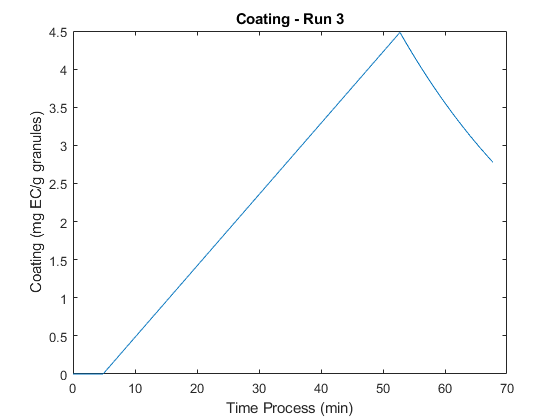

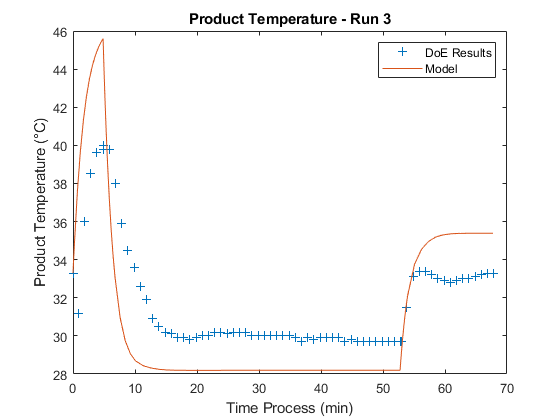

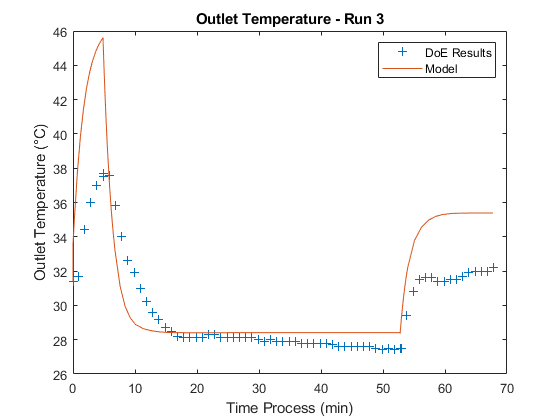

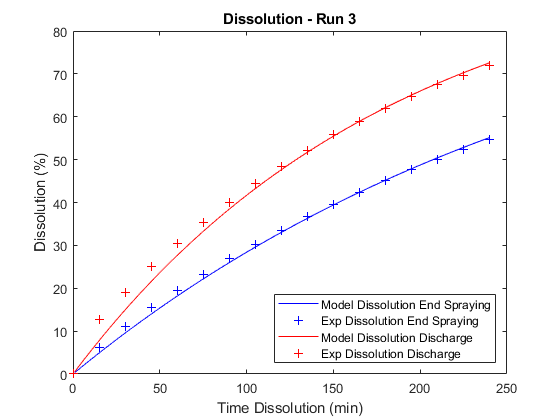

    Time    Dissolution    Exp_Dissolution_EndSpraying    Delta_Disso_ES
    ____    ___________    ___________________________    ______________

      1       0.33362                     0                   0.33362   
     15        4.8891                   6.2                    1.3109   
     30        9.5393                    11                    1.4607   
     45        13.962                  15.4                     1.438   
     60        18.169                19.467                    1.2981   
     75        22.169                23.267                    1.0973   
     90        25.975                26.833                   0.85869   
    105        29.594                  30.3                   0.70615   
    120        33.036                33.533                   0.49722   
    135         36.31                36.667                 

    Time    Dissolution    Exp_Dissolution_Discharge    Delta_Disso_D
    ____    ___________    _________________________    _____________

      1       0.53785                    0                 0.53785   
     15        7.7709               12.633                  4.8624   
     30        14.938               19.067                  4.1287   
     45        21.548               24.967                  3.4186   
     60        27.645               30.367                  2.7221   
     75        33.267                 35.4                  2.1328   
     90        38.453               40.033                  1.5804   
    105        43.236                 44.5                  1.2643   
    120        47.647               48.367                 0.71982   
    135        51.715                 52.2                 0.48483   
    150        55.467  

clear Table_Run
clear PreHeat
clear Spraying
clear Drying
clear ExpData

clear absolute_humidity
clear alpha
clear Average_Drying_Inlet_air_flowrate
clear Average_Drying_Temperature_of_air_flowrate
clear Average_Heating_Inlet_air_flowrate
clear Average_Heating_Temperature_of_air_flowrate
clear Average_Spraying_Inlet_air_flowrate
clear Average_Spraying_Temperature_of_air_flowrate
clear Batch_size
clear coater
clear coater_all
clear coater_results
clear Coating_solution_dry_matter

clear Flow_rate_air
clear Flow_rate_air_drying
clear Flow_rate_air_heating
clear Flow_rate_air_spraying
clear Flow_rate_at
clear Flow_rate_coating
clear Flow_rate_MCP
clear Flow_rate_SAP
clear g
clear Gas_constant
clear Gas_moisture_0
clear HeatTransferCoef_Drying
clear HeatTransferCoef_PreHeating
clear HeatTransferCoef_Spraying
clear Height_bed
clear i
clear j
clear k
clear z1
clear z2
clear z3
clear coating_time
clear Coating_mass_0
clear Coating_solution_dry_matter
clear CoatingMass_Discharge
clear CoatingMass_EndSpraying
clear Conductivity_air
clear cp_acetone_liq
clear cp_c
clear cp_dry_air
clear cp_p
clear cp_v

clear DMC
clear Diameter_bed
clear Diameter_eq
clear Diameter_particle
clear eps
clear External_Diameter_bed
clear External_surface

clear Mass_air
clear Mass_particle
clear N_bed
clear N_parameter
clear Parameter
clear Particle_mositure_0
clear Molecular_weight_5ASA
clear Molecular_weight_acetone
clear Molecular_weight_air

clear Inlet_coating_sprayrate
clear Inlet_gas_moisture_acetone
clear Intern_surface
clear lambda_wall
clear Length_particle
clear ModelDissolution_Discharge
clear ModelDissolution_EndSpraying
clear ModelisationResults
clear Ni_0
clear Particle_moisture_0
clear Pressure
clear Pressure_out

clear Process_parameter
clear Q_lat
clear rho_air
clear rho_particle
clear Run_ID
clear surface
clear Surface_particle

clear t
clear t1
clear t2
clear t3
clear t_data
clear t_model
clear t_span
clear TimeDissolution_Discharge
clear TimeDissolution_EndSpraying

clear Temp_air_drying
clear Temp_air_heating
clear Temp_air_spraying
clear Temp_at
clear Temp_particle_0
clear Temp_wb
clear Temperature_air_0
clear Temperature_of_particule_0

clear Volume_air
clear Volume_bed
clear Volume_particle
clear Wall_Thickness
    
clear DissolutionResults_Discharge
clear DissolutionResults_EndSpraying   






























    
end